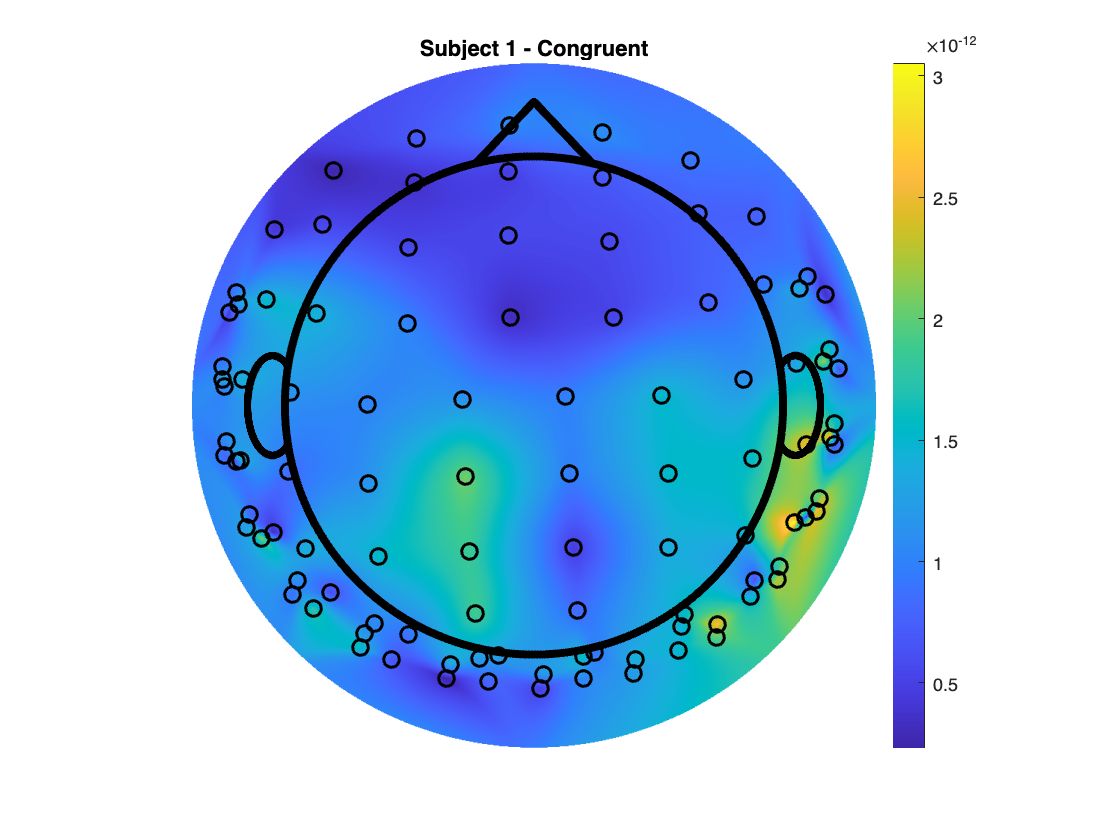

load CIBA120_data.mat

% average activity across epochs and the desired time window (250–600 ms)
n400_window = find(time_points > 250 & time_points < 600);

% Average data for Subject 1
avg_cong_s1 = squeeze(mean(mean(ep_cong_s1(:, :, n400_window), 3), 1));
avg_incong_s1 = squeeze(mean(mean(ep_incong_s1(:, :, n400_window), 3), 1));
% for Subject 2
avg_cong_s2 = squeeze(mean(mean(ep_cong_s2(:, :, n400_window), 3), 1));
avg_incong_s2 = squeeze(mean(mean(ep_incong_s2(:, :, n400_window), 3), 1));

% combining orthogonal gradiometers 
% for Subject 1
avg_cong_s1_combined = abs(avg_cong_s1(1:2:end))' + abs(avg_cong_s1(2:2:end))';
avg_incong_s1_combined = abs(avg_incong_s1(1:2:end))' + abs(avg_incong_s1(2:2:end))';
% for Subject 2
avg_cong_s2_combined = abs(avg_cong_s2(1:2:end))' + abs(avg_cong_s2(2:2:end))';
avg_incong_s2_combined = abs(avg_incong_s2(1:2:end))' + abs(avg_incong_s2(2:2:end))';

% Contrast 
% for Subject 1
contrast_s1 = avg_cong_s1_combined - avg_incong_s1_combined;
% for Subject 2
contrast_s2 = avg_cong_s2_combined - avg_incong_s2_combined;

% Plots for Subject 1 
% Congruent
figure;
plot_topography_mod('all', avg_cong_s1_combined, false, 'grad_loc.mat');
title('Subject 1 - Congruent');

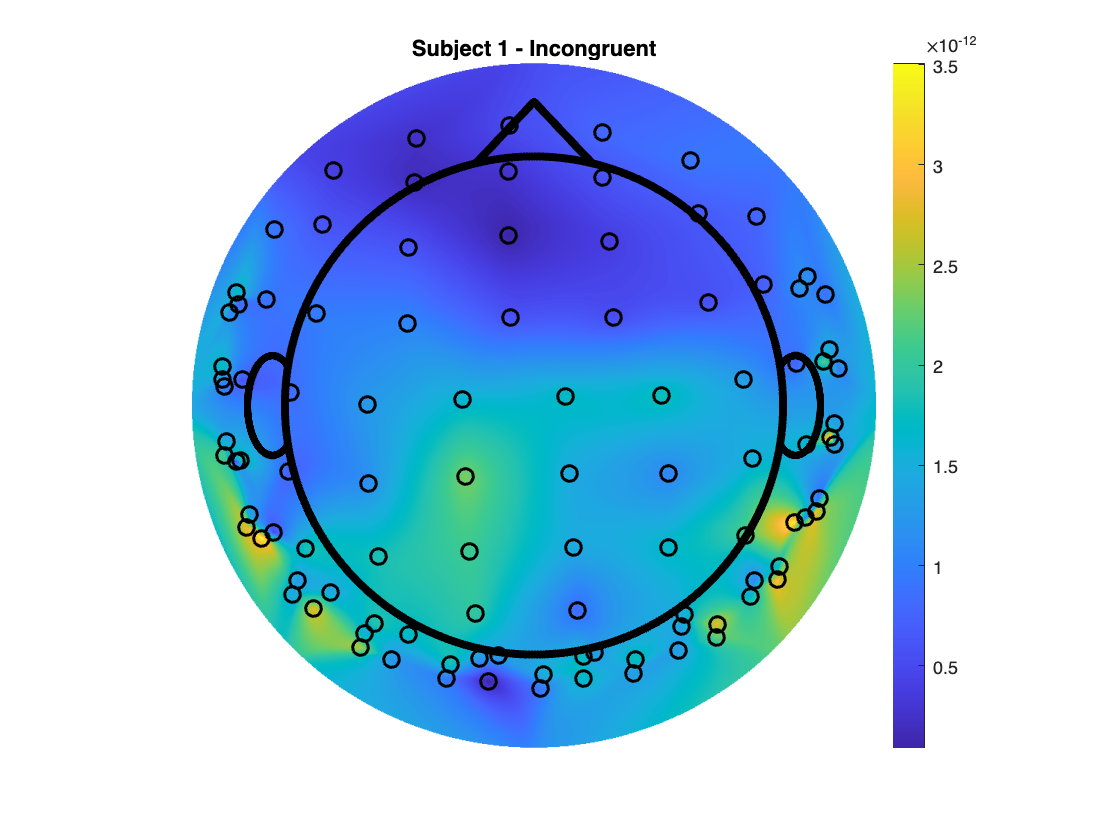

% Incongruent
figure;
plot_topography_mod('all', avg_incong_s1_combined, false, 'grad_loc.mat');
title('Subject 1 - Incongruent');

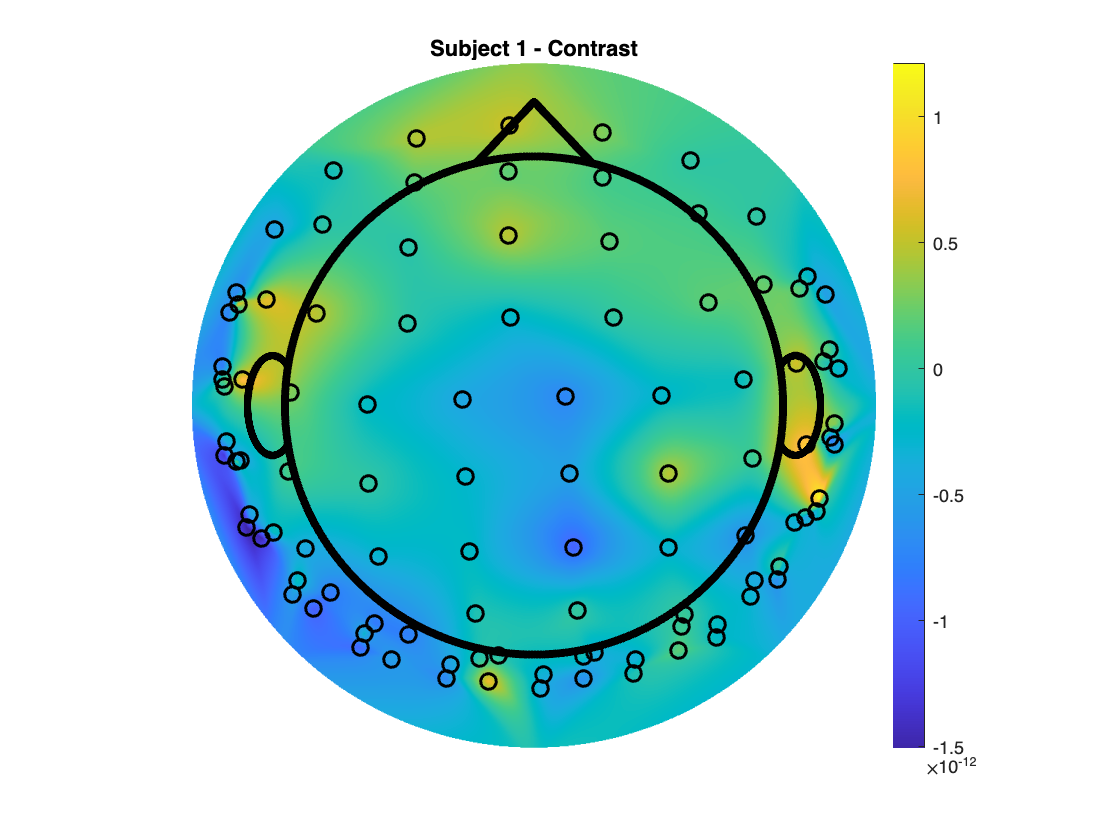

% Contrast
figure;
plot_topography_mod('all', contrast_s1, false, 'grad_loc.mat');
title('Subject 1 - Contrast');

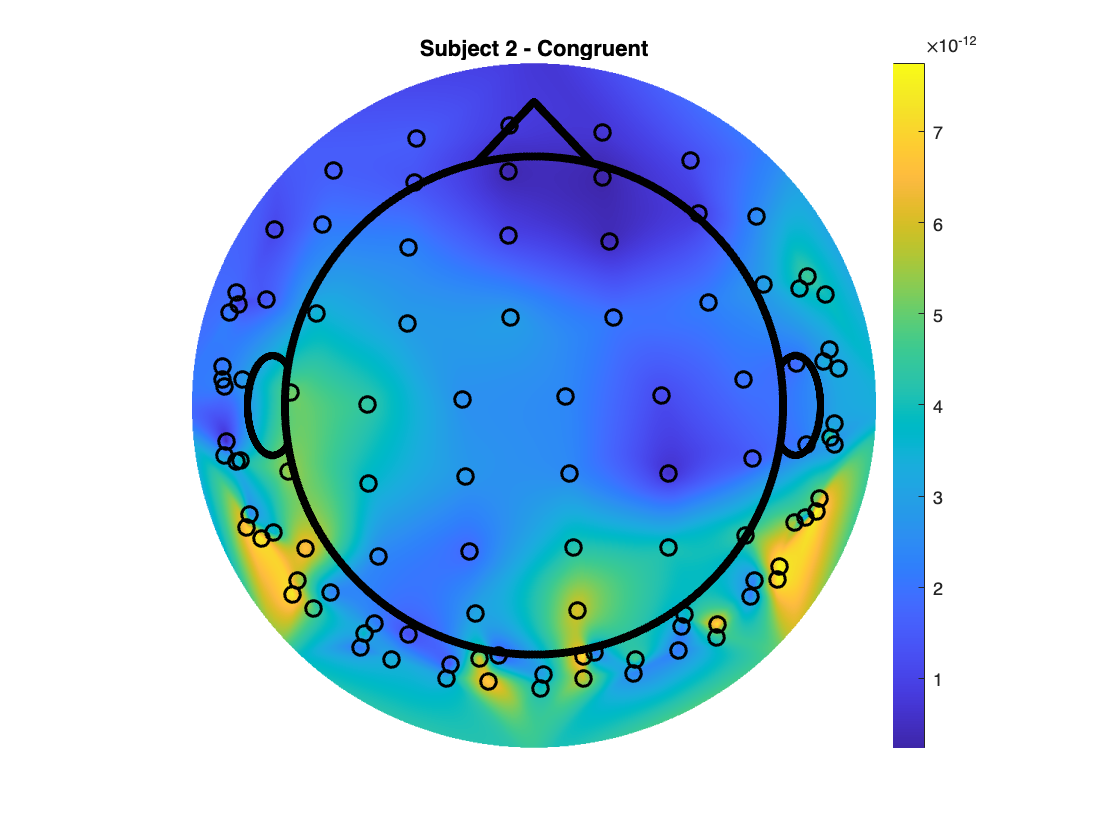


% Plots for Subject 2 
% Congruent
figure;
plot_topography_mod('all', avg_cong_s2_combined, false, 'grad_loc.mat');
title('Subject 2 - Congruent');

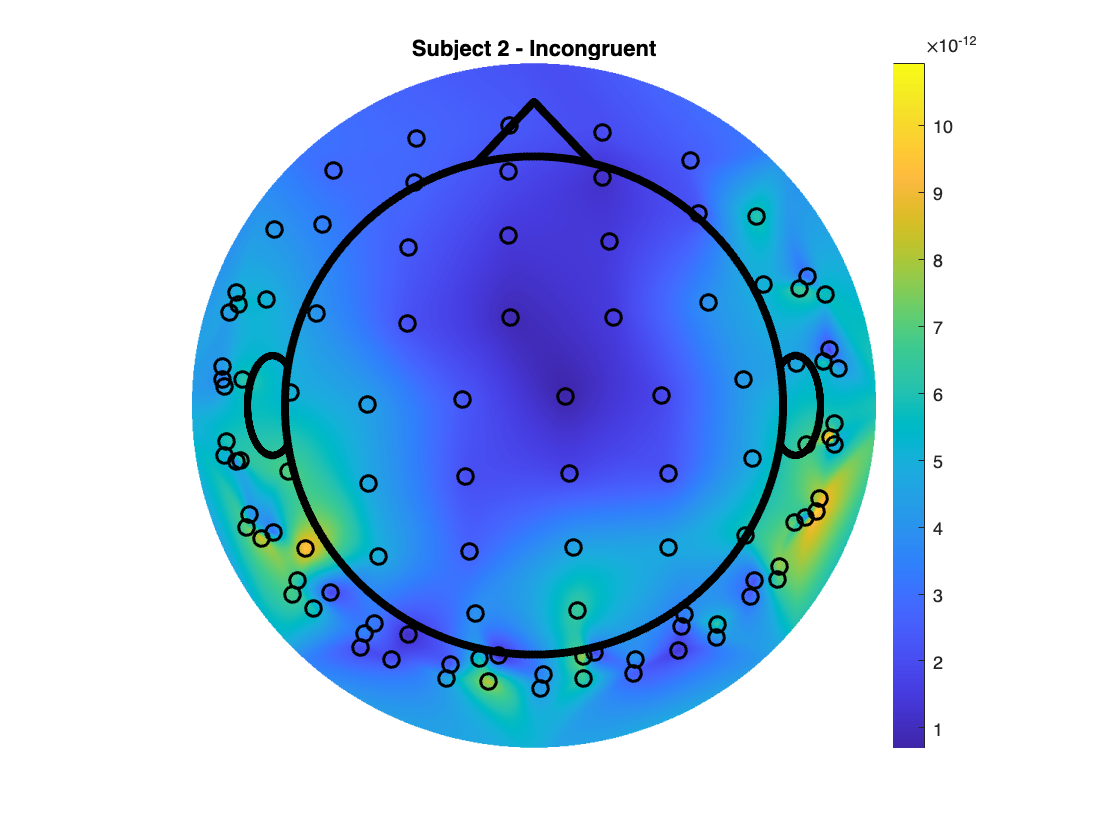

% Incongruent
figure;
plot_topography_mod('all', avg_incong_s2_combined, false, 'grad_loc.mat');
title('Subject 2 - Incongruent');

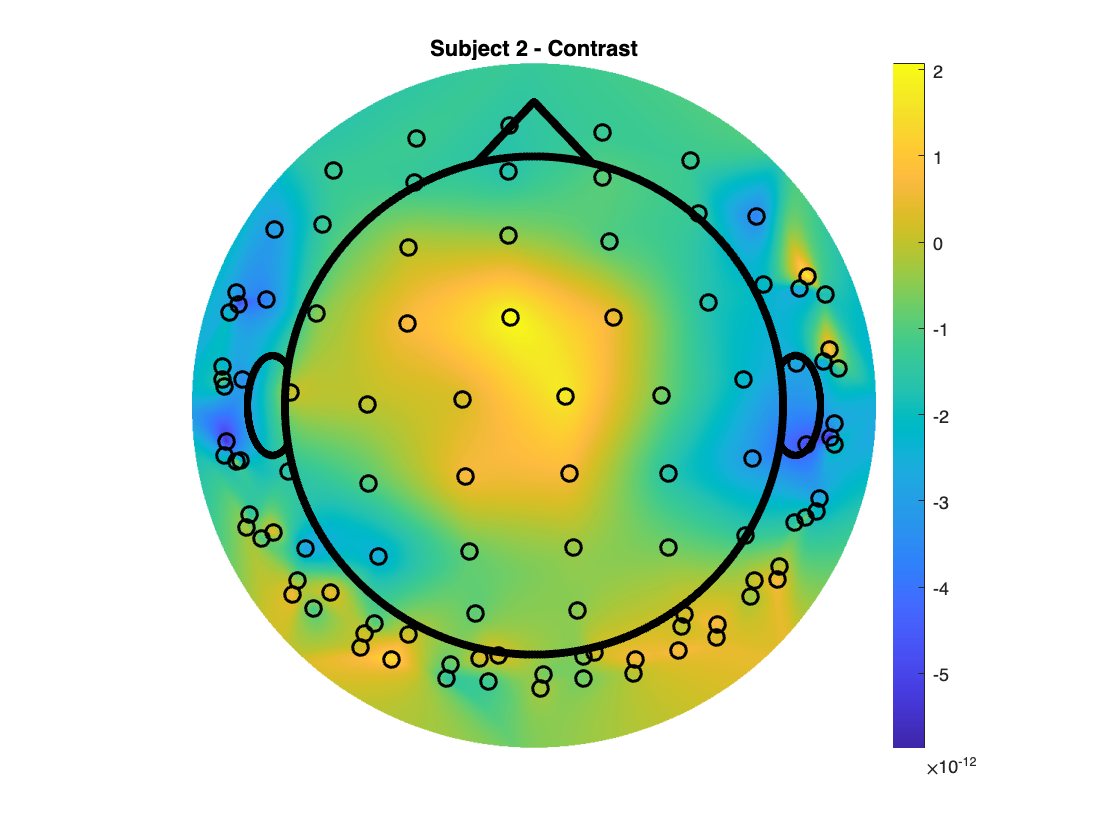

%Contrast
figure;
plot_topography_mod('all', contrast_s2, false, 'grad_loc.mat');
title('Subject 2 - Contrast');